%% CLASIFICACIÓN CON MLP (DEEP LEARNING) - OPTIMIZACIÓN Y COMPARATIVA
close all; clear all; clc;

% --- 1. CARGA Y PREPARACIÓN DE DATOS ---
% Los datos proceden de la base de datos Iris de Fisher 
load('fisheriris.mat'); 
patronEntrada = meas;
claseSalida = species;

% Barajado para eliminar orden preestablecido 
indiceReor = randperm(length(claseSalida));
patron = patronEntrada(indiceReor,:)';
claseSal = claseSalida(indiceReor)';

% Conversión de etiquetas de texto a numéricas para proceso categórico 
clase = zeros(1, length(claseSal));
for i=1:length(claseSal)
    if strcmp(claseSal{i},'setosa'), clase(i)=1;
    elseif strcmp(claseSal{i},'versicolor'), clase(i)=2;
    else, clase(i)=3; end
end

% Formateo a dlarray (Channels, Batches) y labels categóricas 
patrones = dlarray(patron, 'CB'); 
claseCat = categorical(clase);

% --- 2. CONFIGURACIÓN DEL EXPERIMENTO ---
numDatos = size(patron,1);
numClases = 3;
porcenEntVal = 0.20; % 20% para entrenamiento, el resto para validar potencia

% Definición de arquitecturas: 
% Puedes poner una capa {5}, dos {[10, 5]} o las que quieras.
lista_neuronas = {2, 5, [10, 5], [5, 5, 2]}; 
lista_LR       = [0.01, 0.05];       
lista_epochs   = [50, 100];       

resultados_clasif = table();
mejorPrecision = -1;
mejorRed = [];
mejorConfig = "";

% --- 3. BUCLE DE OPTIMIZACIÓN AUTOMÁTICA ---
for nn = 1:length(lista_neuronas)
    for lr = lista_LR
        for ep = lista_epochs
            
            config_actual = lista_neuronas{nn};
            fprintf('Entrenando: Capas=%s | LR=%.3f | Epochs=%d\n', mat2str(config_actual), lr, ep);
            
            % Definición Dinámica de Capas 
            % Creamos la red según el vector de neuronas proporcionado
            capas = featureInputLayer(numDatos);
            for h = 1:length(config_actual)
                capas = [capas; fullyConnectedLayer(config_actual(h)); tanhLayer];
            end
            capas = [capas; fullyConnectedLayer(numClases); softmaxLayer];
            
            % Opciones de Entrenamiento 
            options = trainingOptions("adam", ...
                ExecutionEnvironment="cpu", ...
                MaxEpochs = ep, ...
                InitialLearnRate = lr, ...
                Verbose = false, ...
                Plots = "none");
            
            % División Entrenamiento/Validación 
            longEntre = ceil(porcenEntVal * length(patrones));
            patronEntr = patrones(:, 1:longEntre);
            patronVal  = patrones(:, longEntre+1:end);
            claseEntr  = claseCat(:, 1:longEntre);
            claseValNum = clase(longEntre+1:end);
            
            % Entrenamiento de la red 
            redClasif = dlnetwork(capas);
            % Se transpone claseEntr para que trainnet reciba un vector columna
            redClasif = trainnet(patronEntr, claseEntr', redClasif, 'crossentropy', options);
            
            % Predicción y evaluación 
            prediccionesVal = predict(redClasif, patronVal);
            [~, clasePredicha] = max(prediccionesVal, [], 1);
            clasePredichaNum = extractdata(clasePredicha);
            
            % Precisión Global
            precision = mean(clasePredichaNum(:) == claseValNum(:)) * 100;
            
            % Guardar si es el mejor modelo hasta ahora
            if precision > mejorPrecision
                mejorPrecision = precision;
                mejorRed = redClasif;
                mejorPrediccionData = clasePredichaNum;
                mejorRealData = claseValNum;
                mejorConfig = sprintf('Capas:%s, LR:%.3f, Ep:%d', mat2str(config_actual), lr, ep);
            end
            
            % Añadir a la tabla comparativa
            nueva_fila = table({mat2str(config_actual)}, lr, ep, precision, ...
                'VariableNames', {'Arquitectura', 'LearnRate', 'Epochs', 'Precision_Pct'});
            resultados_clasif = [resultados_clasif; nueva_fila];
        end
    end
end

Entrenando: Capas=2 | LR=0.010 | Epochs=50
Entrenando: Capas=2 | LR=0.010 | Epochs=100
Entrenando: Capas=2 | LR=0.050 | Epochs=50
Entrenando: Capas=2 | LR=0.050 | Epochs=100
Entrenando: Capas=5 | LR=0.010 | Epochs=50
Entrenando: Capas=5 | LR=0.010 | Epochs=100
Entrenando: Capas=5 | LR=0.050 | Epochs=50
Entrenando: Capas=5 | LR=0.050 | Epochs=100
Entrenando: Capas=[10 5] | LR=0.010 | Epochs=50
Entrenando: Capas=[10 5] | LR=0.010 | Epochs=100
Entrenando: Capas=[10 5] | LR=0.050 | Epochs=50
Entrenando: Capas=[10 5] | LR=0.050 | Epochs=100
Entrenando: Capas=[5 5 2] | LR=0.010 | Epochs=50
Entrenando: Capas=[5 5 2] | LR=0.010 | Epochs=100
Entrenando: Capas=[5 5 2] | LR=0.050 | Epochs=50
Entrenando: Capas=[5 5 2] | LR=0.050 | Epochs=100



% --- 4. PRESENTACIÓN DE RESULTADOS ---
disp(' ');

disp('========================================================');

disp('      TABLA COMPARATIVA DE MODELOS (ORDENADA)          ');

      TABLA COMPARATIVA DE MODELOS (ORDENADA)          


disp('========================================================');

% Ordenamos por precisión (mayor a menor) y luego por épocas (menor a mayor para eficiencia)
disp(sortrows(resultados_clasif, {'Precision_Pct', 'Epochs'}, {'descend', 'ascend'}));

    Arquitectura    LearnRate    Epochs    Precision_Pct
    ____________    _________    ______    _____________

    {'5'      }       0.05         50           97.5    
    {'[10 5]' }       0.01         50           97.5    
    {'[10 5]' }       0.05         50           97.5    
    {'[5 5 2]'}       0.05         50           97.5    
    {'[10 5]' }       0.05        100           97.5    
    {'2'      }       0.05        100         96.667    
    {'5'      }       0.05        100         96.667    
    {'[10 5]' }       0.01        100         96.667    
    {'[5 5 2]'}       0.01         50         95.833    
    {'[5 5 2]'}       0.05        100         95.833    
    {'[5 5 2]'}       0.01        100         93.333    
    {'2'      }       0.05         50             90    
    {'5'      }       0.01        100         89.167    
    {'5'


fprintf('\n>>> LA MEJOR CONFIGURACIÓN ENCONTRADA: %s\n', mejorConfig);


>>> LA MEJOR CONFIGURACIÓN ENCONTRADA: Capas:5, LR:0.050, Ep:50


fprintf('>>> PRECISIÓN ALCANZADA: %.2f%%\n', mejorPrecision);

>>> PRECISIÓN ALCANZADA: 97.50%


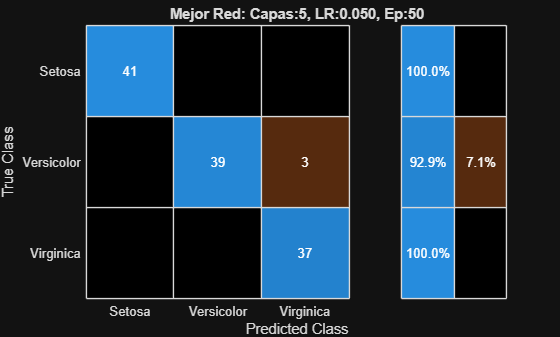


% Matriz de confusión del mejor modelo 
figure;
confusionchart(confusionmat(mejorRealData, mejorPrediccionData), ...
    {'Setosa','Versicolor','Virginica'}, ...
    'Title', ['Mejor Red: ', mejorConfig], ...
    'RowSummary','row-normalized');